# Filtro Autorregresivo

**filtrado autorregresivo (AR)** es una técnica de modelado de series temporales en la que el valor actual de una serie depende de sus valores pasados. Es una forma de modelar una señal como una combinación lineal de sus valores anteriores más un término de error (ruido).

% Generar una señal AR(2) con ruido blanco
N = 500; % Número de muestras
n = 0:N-1;  % Eje temporal

%xn = 20 + 0.05 * n; % Tendencia lineal
xn = 3*cos(2*pi*0.01*n) - 2*sin(2*pi*0.05*n);
ruido = randn(1, N); % Ruido aleatorio
xn_r = xn + ruido;

Numero de terminos pasados

ventana = 5;

Estimacion del filtro AR mediante la funcion ar

modelo_ar = ar(xn_r, ventana);
%coeficientes estimados
coef = [0, -modelo_ar.A(2:end)]

coef =          0    0.6051    0.3379    0.1033   -0.0716   -0.1034


Filtrado de la señal

yn = filter(coef,1,xn_r);

Generando las graficas

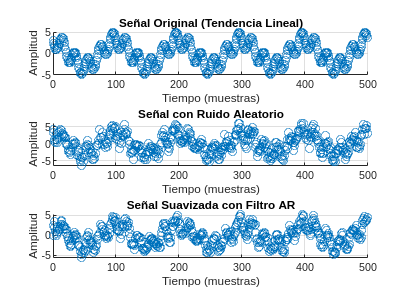

figure()

% Graficar la señal original (tendencia)
subplot(3,1,1);
scatter(n, xn);
title('Señal Original (Tendencia Lineal)');
xlabel('Tiempo (muestras)');
ylabel('Amplitud');
grid on;

% Graficar la señal ruidosa
subplot(3,1,2);
scatter(n, xn_r);
title('Señal con Ruido Aleatorio');
xlabel('Tiempo (muestras)');
ylabel('Amplitud');
grid on;

% Graficar la señal suavizada (filtro AR)
subplot(3,1,3);
scatter(n, yn);
title('Señal Suavizada con Filtro AR');
xlabel('Tiempo (muestras)');
ylabel('Amplitud');
grid on;

## Mediciones sobre las señales

Se aplicaran mediciones para verificar el efecto del filtro AR

Primero entre la señal original y la señal ruidosa

% Error cuadratico medio (MSE)
Err1 = (1/(N-ventana)) *(sum( (xn(ventana:end) - xn_r(ventana:end)) .^ 2))

Err1 = 0.9665

Ahora entre la señal original y la señal suavizada

Err2 = (1/(N-ventana)) *(sum( (xn(ventana:end) - yn(ventana:end)) .^ 2))

Err2 = 0.8537